compute_arm_printable(0, 0, true)

boatMass = 52.9677

centerOfMass =     0.0000    0.9046   -0.5255


d = 0.9694

centerOfBuoyancy =    -0.0000    0.4893   -0.5168


ans =    -0.0000
    0.0087


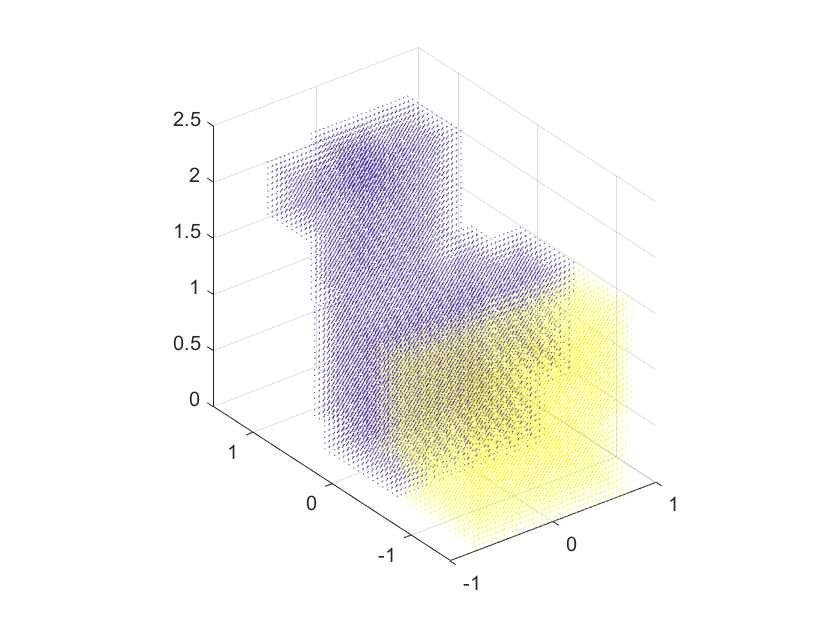


%{
% Moment Arm Surface
pitchVals = linspace(-180, 180, 30);
rollVals = linspace(-180, 180, 30);
[pitch, roll] = meshgrid(pitchVals, rollVals);
momentArms = zeros(size(pitch));
for i = 1:size(momentArms,1)
    for j = 1:size(momentArms,2)
        momentArms(i, j) = norm(compute_arm([pitch(i, j), roll(i, j)]));
    end
end
figure(2)
surface(pitch, roll, momentArms);
xlabel("Pitch (degrees)");
ylabel("Roll (degrees)");
colorbar
view(3)
%}

% Moment Arm Curve
pitchVals = linspace(-180, 180, 100);
rollVals = linspace(-180, 180, 100);
momentArmPitch = zeros(size(pitchVals, 2), 2);
momentArmRoll = zeros(size(rollVals, 2), 2);
hold on;

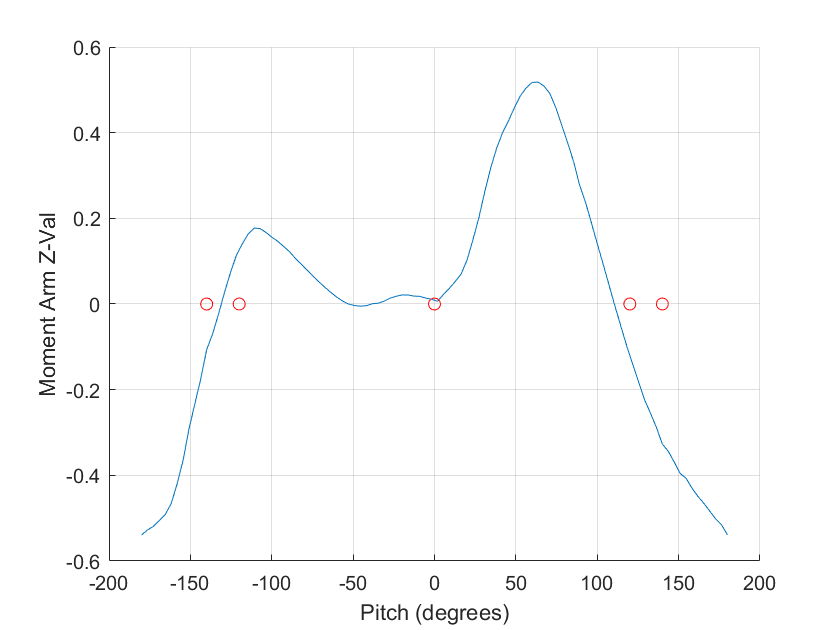


% Varying Pitch
for i = 1:size(momentArmPitch, 1)
    arm = compute_arm([pitchVals(i), 0]);
    momentArmPitch(i, :) = arm';
end

%{
figure(2)
clf
grid on;
hold on;
plot(pitchVals, momentArmPitch(:,1));
plot([0;120;140;-120;-140],[0;0;0;0;0], "or");
xlabel("Pitch (degrees)");
ylabel("Moment Arm X-Val");
hold off;
%}

figure(3)
clf
grid on;
hold on;
plot(pitchVals, momentArmPitch(:,2));
plot([0;120;140;-120;-140],[0;0;0;0;0], "or");
xlabel("Pitch (degrees)");
ylabel("Moment Arm Z-Val");
hold off;

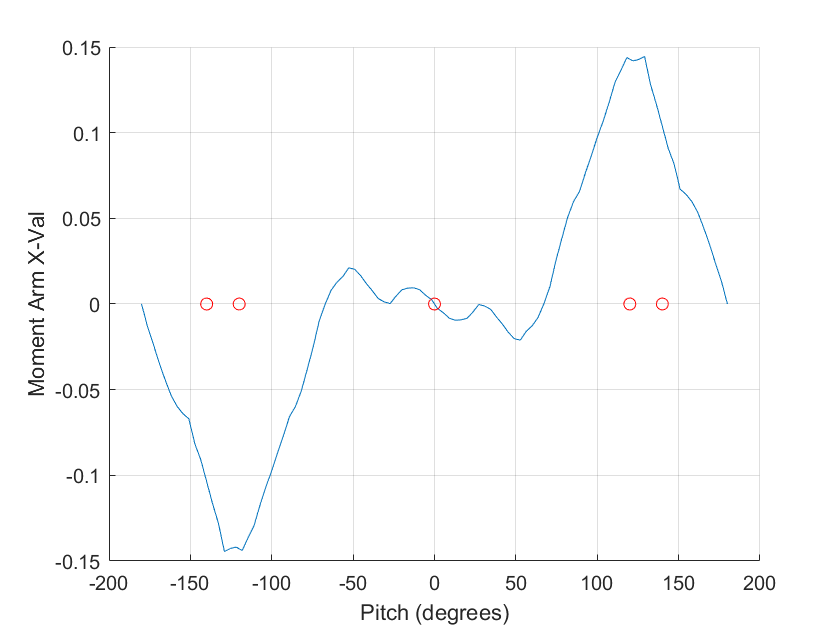


% Varying Roll
for i = 1:size(momentArmRoll, 1)
    arm = compute_arm([0, rollVals(i)]);
    momentArmRoll(i,:) = arm';
end

figure(4)
clf
grid on;
hold on;
plot(rollVals, momentArmRoll(:,1));
plot([0;120;140;-120;-140],[0;0;0;0;0], "or");
xlabel("Pitch (degrees)");
ylabel("Moment Arm X-Val");
hold off;

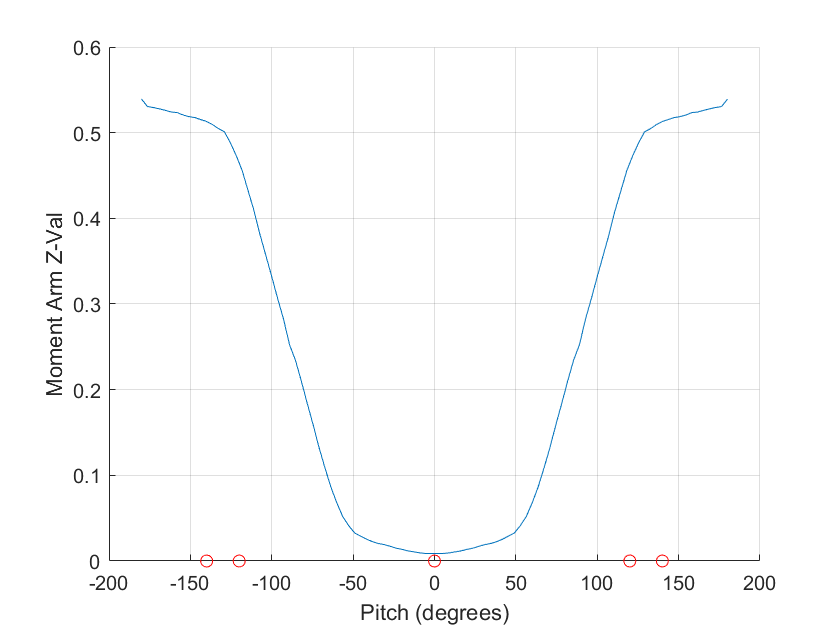


figure(5)
clf
grid on;
hold on;
plot(rollVals, momentArmRoll(:,2));
plot([0;120;140;-120;-140],[0;0;0;0;0], "or");
xlabel("Pitch (degrees)");
ylabel("Moment Arm Z-Val");
hold off;